**Cargar variables de Scope**

clc
clear variables
load('DataLDR.mat')
% Escalon
Input = U;
% Respuesta de motor
Output = Y;

**Abrir herramienta idenficador de sistemas** 

% Escribir en command Window
systemIdentification
% En impor Data configurar 
% IdData = iddata ([Y],[U ],Ts);
% Model = n4sid (IdData,1);
% compare(IdData , Model );

Seleccionar Import y luego close

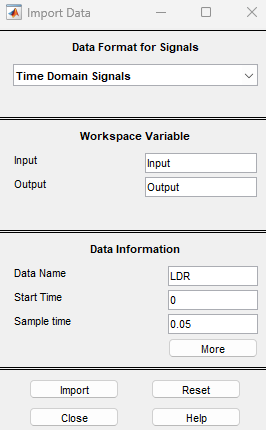

% Seleccione el modelo y luego la opción Select range

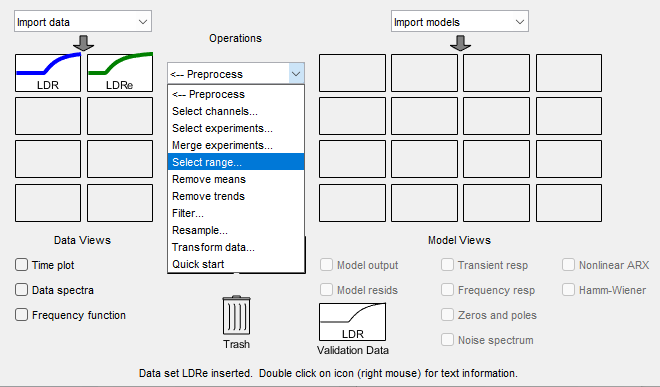

% Seleccione el modelo recortado de color verde y seleccione
% la opción process Model

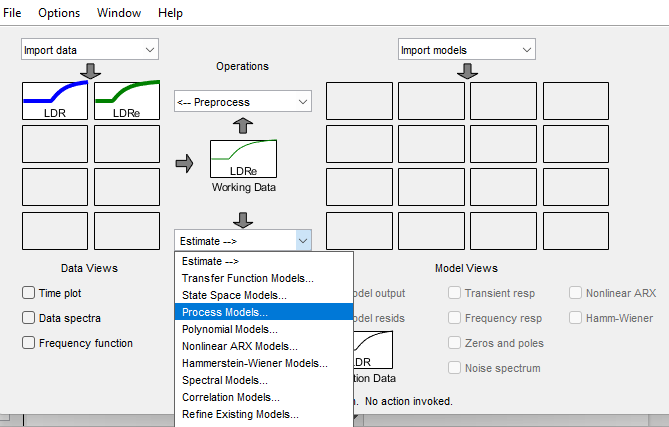

% Desactive delay y Presione estimar 

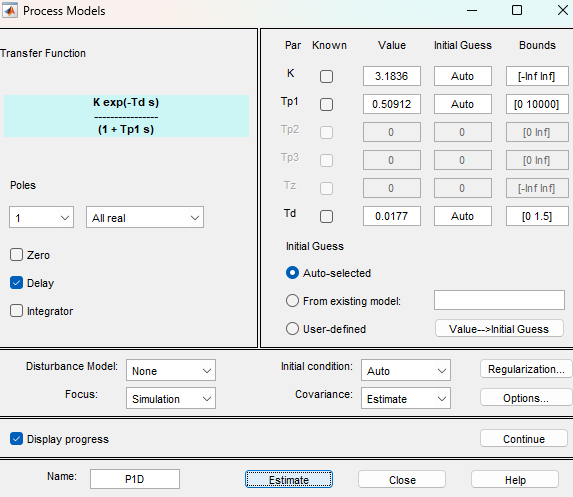

% Click derecho en la planta estimada P1, y presione el botón
% Export

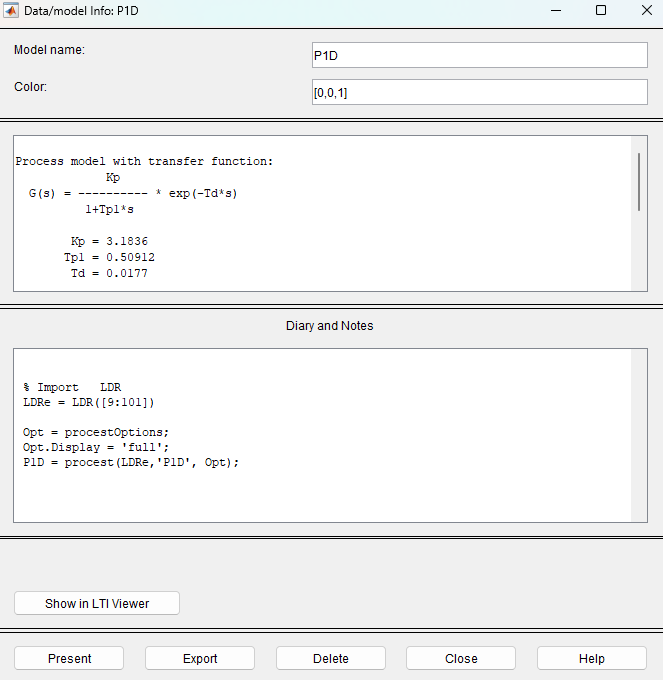

**Guardar planta**

save('Transfer_functionLDR')

**Calculo de periodo de muestreo**

% como Tp1 es 0.50912 es decir Tau
T1= 0.50912/20;
T2= 0.50912/10;
% Promedio entre T1 y T2
 Tss= 0.0355;
% Tss= 0.050;

**Cálculo de ganancias Ziguer Nichols Discreto**

kp = 3.1836;
tau = 0.50912;
theta = 0.0177;
% Retardo discreto 
L = theta + Tss/2;

kc = (1.2*tau)/(kp*L)
ti = 2*L
td = 0.5*L

**Sintonizar Ganancias de controlador **

pidtool

**Convertir la planta tiempo discreto**

c2d(C,0.05,'tustin')